# EE525 - Lab Project 2

Author: Grant Gallagher

Due: 10/15/2021

## 1. Random Walk

### 1.1 Unbiased Random Walk

#### 10 Realizations

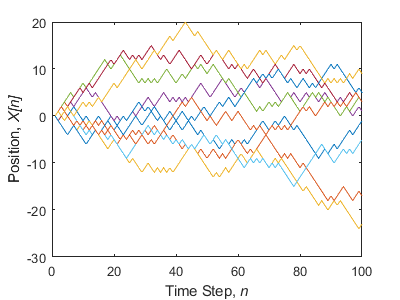

numTimeSteps = 100;
numWalkers = 10;
walkerData = zeros(numWalkers, numTimeSteps); % initialize at zero

% Simulate walk
for t = 2:numTimeSteps
    stepVec = 2*randi(2,numWalkers,1) - 3;
    walkerData(:,t) = walkerData(:,t-1) + stepVec;
end
 
% Plot
fig1 = figure;
fig1.Position = [0 0 400 300];
plot(walkerData')
xlabel('Time Step, {\itn}')
ylabel('Position, {\itX[n]}')
saveas(fig1, '10 Realizations Unbiased.png')

#### **Numerical Simulation for Random Walk Behavior as n → ∞**

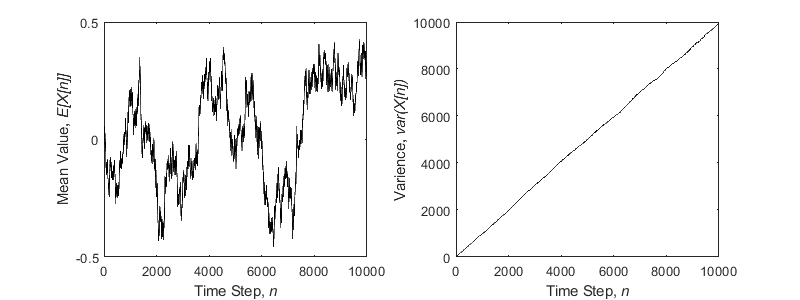

numTimeSteps = 10000; % run 10 thousand time steps
numWalkers   = 10000; % run 1 million walkers
 
% Make Data Storage -> Store as single vector
walkerDataColumn = zeros(numWalkers,1);
meanData = zeros(1,numTimeSteps);
varData = zeros(1,numTimeSteps);
 
% Simulate walk
for t = 2:numTimeSteps
    stepVec = 2*randi(2,numWalkers,1) - 3; % Random Step
    walkerDataColumn = walkerDataColumn + stepVec;
    meanData(t) = average(walkerDataColumn);
    varData(t) = variance(walkerDataColumn);
end
 
% Plot
fig2 = figure;
fig2.Position = [0 0 800 300];
% Mean
subplot(1,2,1)
plot(meanData,'Color',[0 0 0]);
xlabel('Time Step, {\itn}')
ylabel('Mean Value, {\itE[X[n]]}')
% Variance
subplot(1,2,2)
plot(varData,'Color',[0 0 0]);
xlabel('Time Step, {\itn}')
ylabel('Varience, {\itvar(X[n])}')
% Save figure
saveas(fig2, 'Mean-Var Unbiased.png')

### 1.2 Biased Random Walk

#### 10 Realizations

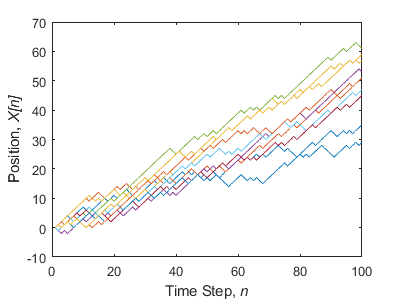

numTimeSteps = 100;
numWalkers = 10;
walkerData = zeros(numWalkers, numTimeSteps); % initialize at zero

% Simulate walk
for t = 2:numTimeSteps
    % use randsample for specific weights
    stepVec = 2*randsample(2,numWalkers,true,[0.25,0.75]) - 3; 
    walkerData(:,t) = walkerData(:,t-1) + stepVec;
end
 
% Plot
fig3 = figure;
fig3.Position = [0 0 400 300];
plot(walkerData')
xlabel('Time Step, {\itn}')
ylabel('Position, {\itX[n]}')
saveas(fig3, '10 Realizations Biased.png')

#### Numerical Simulation for Biased Random Walk Behavior as n → ∞

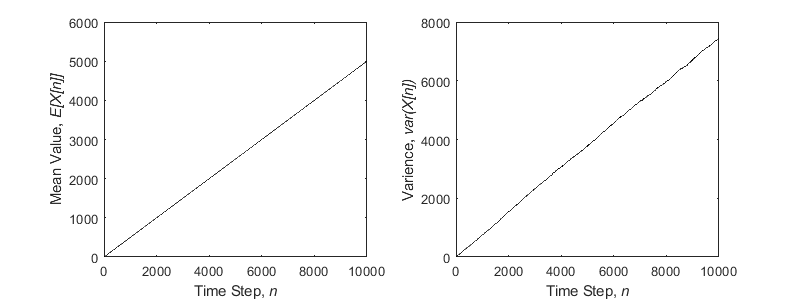

numTimeSteps = 10000; % run 10 thousand time steps
numWalkers   = 10000; % run 1 million walkers
 
% Make Data Storage -> Store as single vector
walkerDataColumn = zeros(numWalkers,1);
meanData = zeros(1,numTimeSteps);
varData = zeros(1,numTimeSteps);
 
%Simulate Walk
for t = 2:numTimeSteps
    % use randsample for specific weights
    stepVec = 2*randsample(2,numWalkers,true,[0.25,0.75]) - 3;
    walkerDataColumn = walkerDataColumn + stepVec;
    meanData(t) = average(walkerDataColumn);
    varData(t) = variance(walkerDataColumn);
end
 
% Plot
fig4 = figure;
fig4.Position = [0 0 800 300];
% Mean
subplot(1,2,1)
plot(meanData,'Color',[0 0 0]);
xlabel('Time Step, {\itn}')
ylabel('Mean Value, {\itE[X[n]]}')
% Varience
subplot(1,2,2)
plot(varData,'Color',[0 0 0]);
xlabel('Time Step, {\itn}')
ylabel('Varience, {\itvar(X[n])}')
% Save figure
saveas(fig4, 'Mean-Var Biased.png')

## 2. Weather Data Analysis

% Initialization
clc
clear

% Filter data
raw_data = readtable('raw_temp_data.csv');
temps_la = get_weather(raw_data, 'LOS ANGELES DOWNTOWN USC, CA US');
temps_sf = get_weather(raw_data, 'SAN FRANCISCO DOWNTOWN, CA US');
temps_dc = get_weather(raw_data, 'COLLEGE PARK, MD US');

### 2.1 Average Temperatures

#### Los Angeles

fig5 = figure(5);
fig5.Position = [0 0 800 300];
% Average Temperature Plots
subplot(1,2,1);
[a, b] = least_squares(temps_la, 'Tavg')

a = 0.0372

b = -8.0244

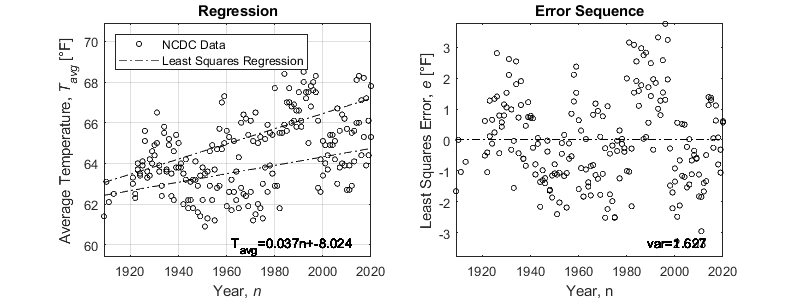

plot_regression(temps_la, a, b, 'Tavg')
title('Regression')

% Average Temperature Error Sequence
subplot(1,2,2);
plot_errors(temps_la, a, b, 'Tavg')
title('Error Sequence')
saveas(fig5, 'LA Average Temperatures.jpg');

#### San Francisco

fig6 = figure(6);
fig6.Position = [0 0 800 300];

% Average Temperature Plots
subplot(1,2,1);
[a, b] = least_squares(temps_sf, 'Tavg')

a = 0.0150

b = 27.8750

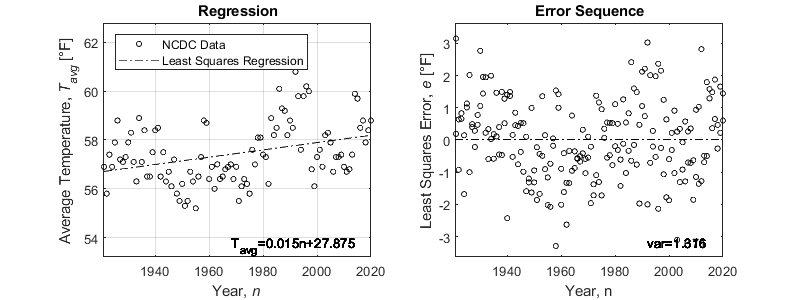

plot_regression(temps_sf, a, b, 'Tavg')
title('Regression')

% Average Temperature Error Sequence
subplot(1,2,2);
plot_errors(temps_sf, a, b, 'Tavg')
title('Error Sequence')
saveas(fig6, 'SF Average Temperatures.jpg');

#### Washington DC

fig7 = figure(7);
fig7.Position = [0 0 800 300];

% Average Temperature Plots
subplot(1,2,1);
[a, b] = least_squares(temps_dc, 'Tavg')

a = 0.0486

b = -38.2975

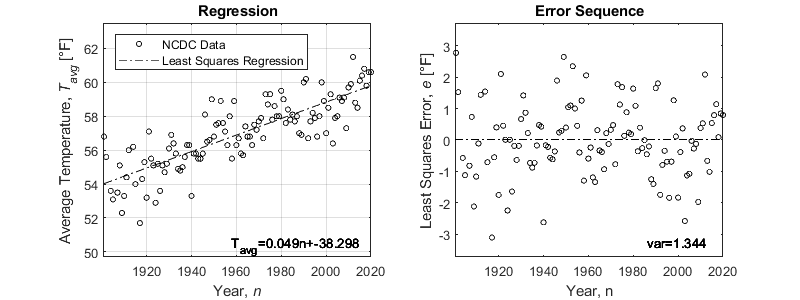

plot_regression(temps_dc, a, b, 'Tavg')
title('Regression')

% Average Temperature Error Sequence
subplot(1,2,2);
plot_errors(temps_dc, a, b, 'Tavg')
title('Error Sequence')
saveas(fig7, 'DC Average Temperatures.jpg');

### 2.2 Maximum Temperatures

#### Los Angeles

fig8 = figure(8);
fig8.Position = [0 0 800 300];

% Maximum Temperature Plots
subplot(1,2,1);
[a, b] = least_squares(temps_la, 'Tmax')

a = 0.0385

b = -1.3932

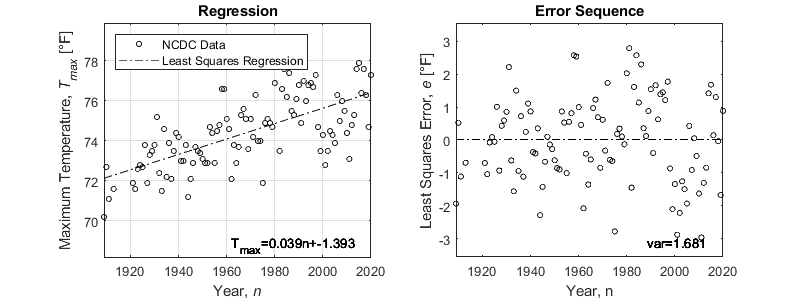

plot_regression(temps_la, a, b, 'Tmax')
title('Regression')

% Maximum Temperature Error Sequence
subplot(1,2,2);
plot_errors(temps_la, a, b, 'Tmax')
title('Error Sequence')
saveas(fig8, 'LA Max Temperatures.jpg');

#### San Francisco

fig9 = figure(9);
fig9.Position = [0 0 800 300];

% Maximum Temperature Plots
subplot(1,2,1);
[a, b] = least_squares(temps_sf, 'Tmax')

a = 0.0207

b = 22.9098

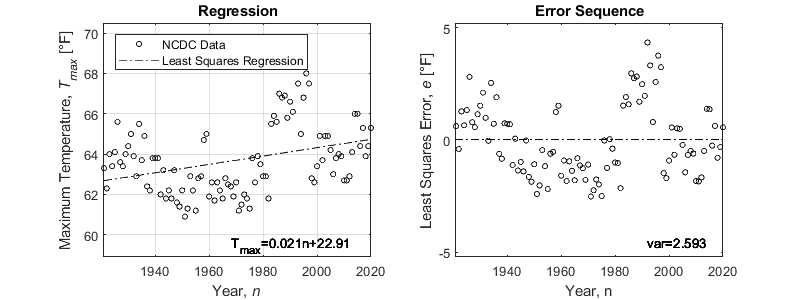

plot_regression(temps_sf, a, b, 'Tmax')
title('Regression')

% Maximum Temperature Error Sequence
subplot(1,2,2);
plot_errors(temps_sf, a, b, 'Tmax')
title('Error Sequence')
saveas(fig9, 'SF Max Temperatures.jpg');

#### Washington DC

fig10 = figure(10);
fig10.Position = [0 0 800 300];

% Maximum Temperature Plots
subplot(1,2,1);
[a, b] = least_squares(temps_dc, 'Tmax')

a = 0.0091

b = 48.9770

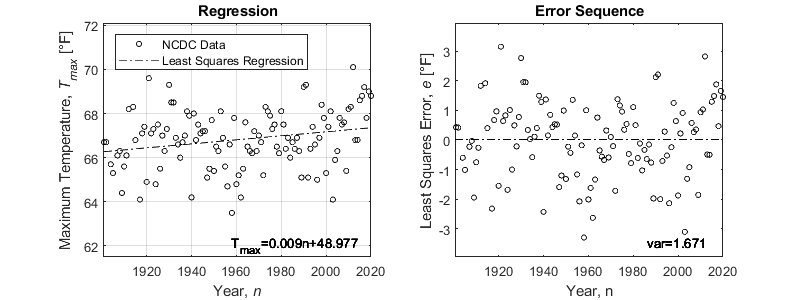

plot_regression(temps_dc, a, b, 'Tmax')
title('Regression')


% Maximum Temperature Error Sequence
subplot(1,2,2);
plot_errors(temps_dc, a, b, 'Tmax')
title('Error Sequence')
saveas(fig10, 'DC Max Temperatures.jpg');

## 3. Appendices

### 3.1 average()

function mu = average(S)
    mu = sum(S)/length(S);
end

### 3.2 variance()

function sigma_2 = variance(S)
    sigma_2 = sum((S-average(S)).^2)/(length(S)-1);
end

### 3.3 get_weather()

function temperature_history = get_weather(raw_data, location)
    % Extract temperatures and years
    years = raw_data.DATE(string(raw_data.NAME) == location);
    average_temperatures = raw_data.TAVG(string(raw_data.NAME) == location);
    max_temperatures = raw_data.TMAX(string(raw_data.NAME) == location);
    % Return valid data points
    temperature_history = rmmissing([years average_temperatures max_temperatures]);
end

### 3.4 least_squares()

function [a, b] = least_squares(data, temperature)
    % Determine which set of data to analyze
    if temperature == 'Tavg'
        idx = 2;
    elseif temperature == 'Tmax'
        idx = 3;
    else
        disp('Error.');
        return
    end
   
    % Calculate the average values for n and x[n]
    n_avg = average(data(:,1));
    x_avg = average(data(:,idx));
    
    % Calculate the 'Sum of Squares' and 'Sum of Products'
    SP = sum((data(:,1)-n_avg).*(data(:,idx)-x_avg));
    SS = sum((data(:,1)-n_avg).^2);
    
    % Calculate the values for a and b
    a = SP/SS;
    b = x_avg - a*n_avg;
end

### 3.5 plot_regression()

function plot_regression(data, a, b, temperature)
    % Determine which set of data to analyze
    if temperature == 'Tavg'
        idx = 2;
    elseif temperature == 'Tmax'
        idx = 3;
    else
        disp('Error.');
        return
    end
    
    % Plot the data and best fit line
    syms x
    hold on
    plot(data(:,1), data(:,idx),'o','Color',[0 0 0],'MarkerSize',4);
    fplot(a*x+b,'-.','Color',[0 0 0]);
    hold off
    grid on
    box on

    % Format the plot
    xlim([min(data(:,1)) max(data(:,1))]);
    ylim([min(data(:,idx))-2 max(data(:,idx))+2]);
    legend('NCDC Data','Least Squares Regression', 'Location','NorthWest');
    xlabel('Year, {\itn}')
    if temperature == 'Tavg'
        ylabel('Average Temperature, {\itT_{avg}} [°F]');
        str = 'T_{avg}='+string(round(a,3))+'n+'+string(round(b,3));
    elseif temperature == 'Tmax'
        ylabel('Maximum Temperature, {\itT_{max}} [°F]');
        str = 'T_{max}='+string(round(a,3))+'n+'+string(round(b,3));
    end
    dim = [0.28 .175 .06 .06];
    annotation('textbox',dim,'String',str,'EdgeColor','none');
end

### 3.6 plot_errors()

function plot_errors(data, a, b, temperature)
    % Determine which set of data to analyze
    if temperature == 'Tavg'
            idx = 2;
        elseif temperature == 'Tmax'
            idx = 3;
        else
            disp('Error.');
            return
    end
    
    % Calculate the error sequence
    e = length(data);
    for n = 1:length(data)
        e(n) = data(n,idx)-(a*data(n,1)+b);
    end
    
    % Plot the error sequence
    hold on
    plot(data(:,1),e,'o','Color',[0 0 0],'MarkerSize',4)
    yline(0,'-.','Color',[0 0 0]);
    hold off
    box on
   
    % Format the plot
    xlim([min(data(:,1)) max(data(:,1))]);
    ylim([-max(abs(e))*1.2 max(abs(e))*1.2]);
    xlabel('Year, n');
    ylabel('Least Squares Error, {\ite} [°F]');
    se = variance(e);
    str = 'var='+string(round(se,3));
    dim = [0.8 .175 .06 .06];
    annotation('textbox',dim,'String',str,'EdgeColor','none');
end